# Control en dos bucles

% Intento de lqi (posicion) en cascada con lqr (actitud)
clear, clc
g = 9.81;
m = 1.6;
Jn = [0.021915027 0.022124548 0.042349865];
Tse = 1/100; % bucle externo (posicion) 100 Hz
Tsi = 1/510; % bucle interno (actitud) 510 Hz

## Modelos

A = [zeros(3) eye(3);
    zeros(3,6)];
Be = [zeros(3);
    0 g 0;
    -g 0 0;
    0 0 1/m];
Bi = [zeros(3);
    diag(power(Jn,-1))];
C = [eye(3) zeros(3)];
D = zeros(3);

bucle_ex = {'StateName',{'x', 'y', 'z', 'vx', 'vy', 'vz'}, 'InputName', {'phi', 'theta', 'F'}, 'OutputName', {'x', 'y', 'z'}};
bucle_in = {'StateName',{'phi', 'theta', 'psi', 'p', 'q', 'r'}, 'InputName', {'Tx', 'Ty', 'Tz'}, 'OutputName', {'phi', 'theta', 'psi'}};

dsyse = c2d(ss(A,Be,C,D,bucle_ex{:}),Tse);
dsysi = c2d(ss(A,Bi,C,D,bucle_in{:}),Tsi);
%clear A Bi Be C D m g

## Pruebas

% Interno
rank(ctrb(dsysi.A,dsysi.B))

ans = 6

rank(obsv(dsysi.A,dsysi.C))

ans = 6

% Externo
rank(ctrb(dsyse.A,dsyse.B))

ans = 6

rank(obsv(dsyse.A,dsyse.C))

ans = 6

## Controladores - LQR

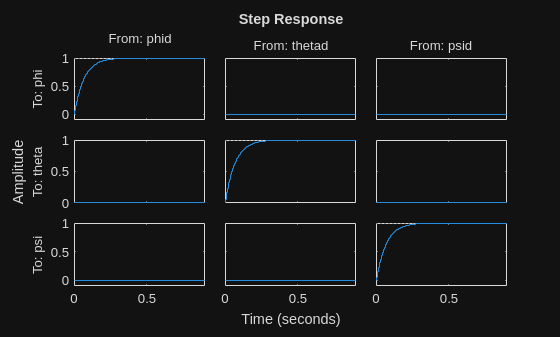

% Interno - actitud
Q = diag(power(deg2rad([5 5 5 15 15 15]),-2));
R = diag(power([4 4 4],-2));
% Q = diag([20 20 25 40 40 45]);
% R = diag([0.001 0.001 0.001]);
[Ki, ~, Pi] = dlqr(dsysi.A,dsysi.B,Q,R);
N = inv(dsysi.C*((eye(6)-dsysi.A+dsysi.B*Ki)\dsysi.B)); % Precompensador
bucle_in = {'StateName',{'phi', 'theta', 'psi', 'p', 'q', 'r'}, 'InputName', {'phid', 'thetad', 'psid'}, 'OutputName', {'phi', 'theta', 'psi'}};
step(ss(dsysi.A-dsysi.B*Ki,dsysi.B*N,dsysi.C,dsysi.D,Tsi, bucle_in{:}))

## LQI solo altura

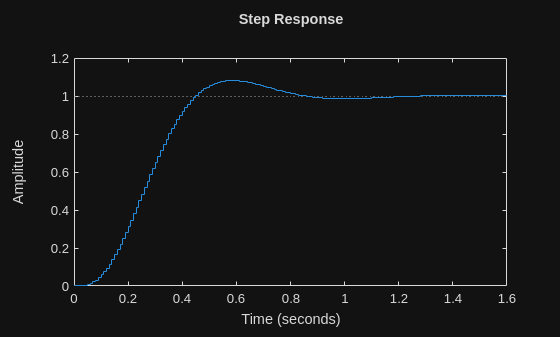

Aa = [0 1; 0 0];
Ba = [0 1/m]';
Ca = [1 0];
Da = 0;
dsysa = c2d(ss(Aa,Ba,Ca,Da),Tse);
Q = diag(power([1 15 0.2],-2));
R = diag(power(2,-2));

% AA = [[1;0;0] [dsysa.C;dsysa.A]];
% BB = [zeros(size(dsysa.B,2),size(dsysa.B,2));dsysa.B];
AA = [[dsysa.A;-dsysa.C] [0;0;1]];
BB = [dsysa.B;0];
[Ka,~,~] = dlqr(AA,BB,Q,R);
step(ss(AA-BB*Ka,[0;0;1],[dsysa.C 0],0,Tse))

## LQI

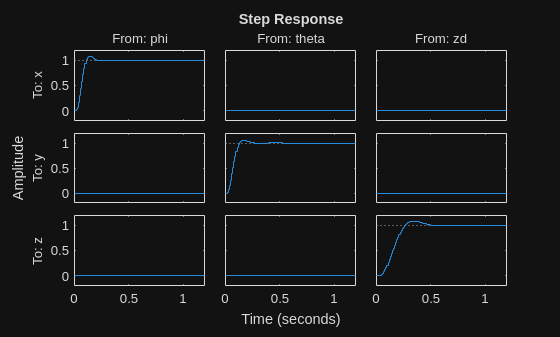

% Externo - posicion
% no va asi, debe estar el modelo lqr en el lqi, lqi necesita de los
% ajustes de lqr
Q = diag(power([1 1 1 8 1 1 0.1 0.1 0.1],-2));
R = diag(power([5 5 5],-2));
AA = [[dsyse.A;-dsyse.C] [zeros(size(dsyse.A,1),size(dsyse.B,2));eye(size(dsyse.C,1));]];
BB = [dsyse.B; zeros(size(dsyse.B,2),size(dsyse.B,2))];
[Ke,~,P] = dlqr(AA,BB,Q,R);

bucle_ex = {'StateName',{'x', 'y', 'z', 'vx', 'vy', 'vz', 'ex', 'ey', 'ez'}, 'InputName', {'phi', 'theta', 'zd'}, 'OutputName', {'x', 'y', 'z'}};
step(ss(AA-BB*Ke,[zeros(size(dsyse.A,1),size(dsyse.B,2));eye(size(dsyse.B,2))],[dsyse.C zeros(size(dsyse.C,1),size(dsyse.B,2))],zeros(size(dsyse.C,1),size(dsyse.B,2)),Tse,bucle_ex{:}))